clear
s = tf('s');
j=0.0019;
b=0.00826;
k=0.6741;
ke=0.6741;
% motor 1:
R=12;
L=90*10^-6;


T=1/200;
td = 6.8; %skifter volsomt fra 6.7 til 6.8
Ti= 10;
K_p = 10;

% Mangler bedre b værdi bedre inertimoment

%controller
G=K_p*(1+td*s+Ti*1/s);
%delay
Gd= 1/(T/(2*s)+1);

%plant
sys = ((k)/((((j*s+b)*(L*s+R)+k^2))))

sys =
 
               0.6741
  --------------------------------
  1.71e-07 s^2 + 0.0228 s + 0.5535
 
Continuous-time transfer function.



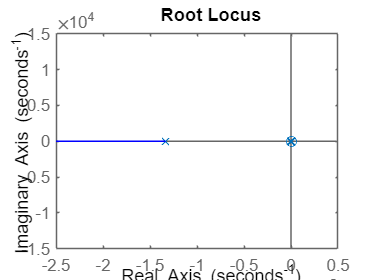


rlocus(sys*Gd*G)

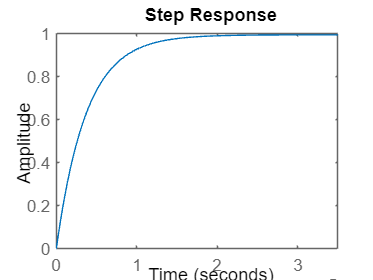


K_p = 1;

G=K_p*(1+td*s+Ti*1/s);
syscl = sys*Gd*G/(1+sys*Gd*G);


step(syscl)